Read images

folder = "DB0"; %%locate folder
imagefiles = dir(fullfile(folder,'*.jpg')); %%store the images
nfiles = length(imagefiles); %%define number of images.

%%for each image
for i = 1:nfiles
  filename=fullfile(folder,imagefiles(i).name); %%get filename of current image.
  %subplot(nfiles/2, nfiles/2, i); %%define location to plot the image in our subplot.
  Im{i}=im2double(imread(filename)); %%Read the imagefile, convert to double and store it.
  %imshow(Im{i}) %%Show the current image in a subplot.
end

Convert to YCbCr and create an eye map according to the *Face Detection in Color Images* paper.

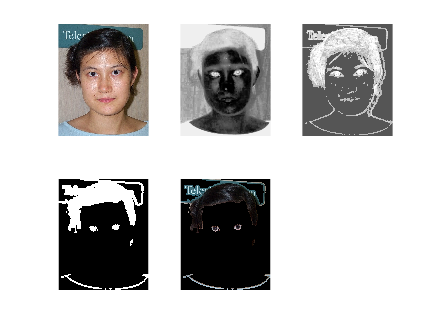

%The following requires image processing toolbox.
currentImage = Im{3};
YCbCr = rgb2ycbcr(currentImage); %%convert the first image in our folder to YCbCr.
[Y, Cb, Cr] = imsplit(YCbCr); %%split the image into Y, Cb and Cr.
Y = uint16(255 * mat2gray(Y)); %%normalize to interval [0,255]
Cb = uint16(255 * mat2gray(Cb)); %%normalize to interval [0,255]
Cr = uint16(255 * mat2gray(Cr)); %%normalize to interval [0,255]

EyeMapC = (1/3) *(Cb.^2 + (255 - Cr).^2 + (Cb./Cr)); %%Chroma eye map.
chromaIm = im2double(histeq(EyeMapC)); %%Convert to double

SE = strel('disk', 4); %Strukturelement, can assume different shapes. 
%Erosion (imerode(IM, SE)) = krympning, used for object separation. 
%Dilation (imdilate(IM,SE)) = Expansion, used to fill holes and gaps. 
EyeMapL = imdilate(Y, SE) ./ (imerode(Y, SE) + 1); %%Luma eye map.
lumaIm = im2double(histeq(EyeMapL));

EyeMap = histeq(chromaIm.*lumaIm); %%Create the combined eye map. 
%%The resulting eye map is then dilated, masked and normalized to brighten
%%both the eyes and suppress other facial areas....and then
%%iterative thresholding is used on this eye map.
EyeMap = (EyeMap - min(EyeMap(:))) / (max(EyeMap(:)) - min(EyeMap(:))); %%Normalize
Threshold = 0.85;
EyeMap = EyeMap > Threshold;
EyeMap = imdilate(EyeMap, SE);

%%Create a figure and subplot the eye maps. 
figure;
subplot(2,3,1);
imshow(currentImage);
subplot(2,3,2);
imshow(chromaIm)
subplot(2,3,3);
imshow(lumaIm);
subplot(2,3,4);
imshow(EyeMap);
subplot(2,3,5);
imshow(EyeMap.*currentImage);

Mouth map

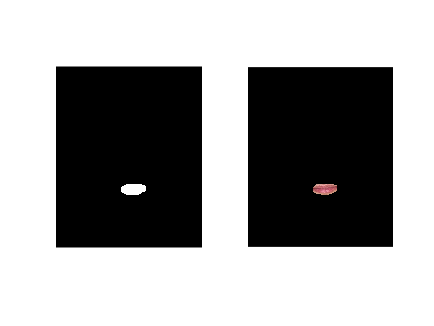

Cb = mat2gray(Cb) + 1;
Cr = mat2gray(Cr) + 1;
n = 0.95 * mean(Cr(:).^2)./(mean(Cr(:)./Cb(:))); %%n is an estimated ratio between Cr^2 and Cr/Cb.
MouthMap = (Cr.^2).*((Cr.^2) - n * (Cr./Cb)).^2; %%Formula for the mouth map.
MouthMap = (MouthMap- min(MouthMap(:)))/(max(MouthMap(:)) - min(MouthMap(:))); %%Normalize

SE = strel('disk', 6);
Threshold = 0.15;
MouthMap = MouthMap > Threshold;
MouthMap = imopen(MouthMap, SE); %%remove small objects
MouthMap = imclose(MouthMap, SE); %%remove small objects
MouthMap = imdilate(MouthMap, SE); %%Increase size.

figure;
subplot(1,2,1);
imshow(MouthMap);
subplot(1,2,2);
imshow(currentImage.*MouthMap);